load iris.mat




type = 'classification';
gam = 1e10

gam = 1.0000e+10

% t = 1;
% degree = 20;
% 
% kpar = [t ; degree];

sig2 = 1;
kpar = sig2;

kernel_type = 'RBF_kernel';

% Find the support values and the bias term of a
% Least Squares Support Vector Machine

[alpha,b] = trainlssvm({Xtrain,Ytrain,type,gam,kpar,kernel_type});

% Evaluate the LS-SVM at the given points

Ypred = simlssvm({Xtrain,Ytrain,type,gam,kpar,kernel_type,'preprocess'},{alpha,b},Xtest);


eval = Evaluate(Ytest,Ypred);
disp('accuracy');

accuracy


disp(eval(1));

    0.9000




% plotconfusion(Ytest',Ypred')
C = confusionchart(Ytest,Ypred)

C =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 double]

  Show all properties


% plot the LS-SVM results in the environment of the training data 

plotlssvm({Xtrain,Ytrain,type,gam,kpar,kernel_type,'preprocess'},{alpha,b});

Start Plotting...

finished


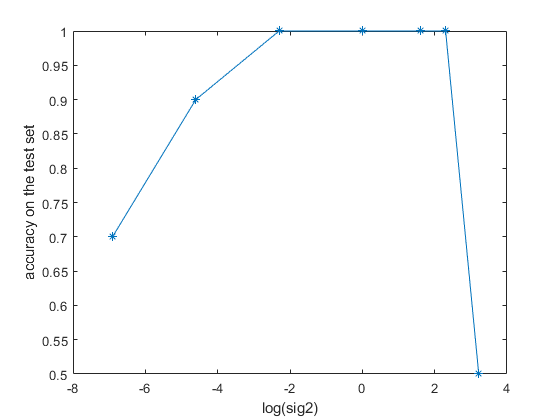

sig2list=[0.001, 0.01, 0.1, 1, 5, 10, 25];
acclist=[0.7, 0.9, 1, 1, 1, 1, 0.5];

figure;
plot(log(sig2list), acclist, '*-'), 
xlabel('log(sig2)'), ylabel('accuracy on the test set'),

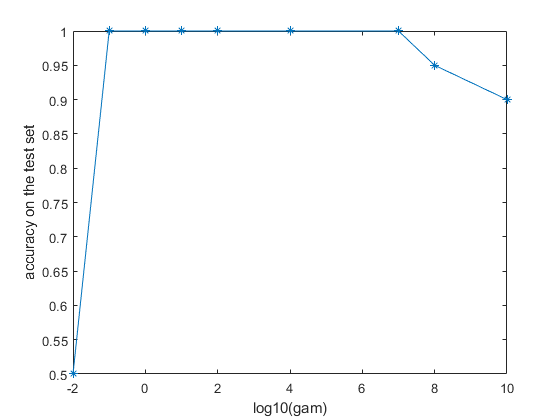

gamlist=[1e-2 1e-1 1e0 1e1 1e2 1e4 1e7 1e8 1e10];
acclist=[0.5 1 1 1 1 1 1 0.95 0.9 ];

figure;
plot(log10(gamlist), acclist, '*-'), 
xlabel('log10(gam)'), ylabel('accuracy on the test set')